## RR One Degree of Freedom Simulation

%clear;
%load('RR.mat');
%open_system('RR_1DOF.slx');

### Level Flight

Note: ran simlink model and renamed out to l_out in workspace.

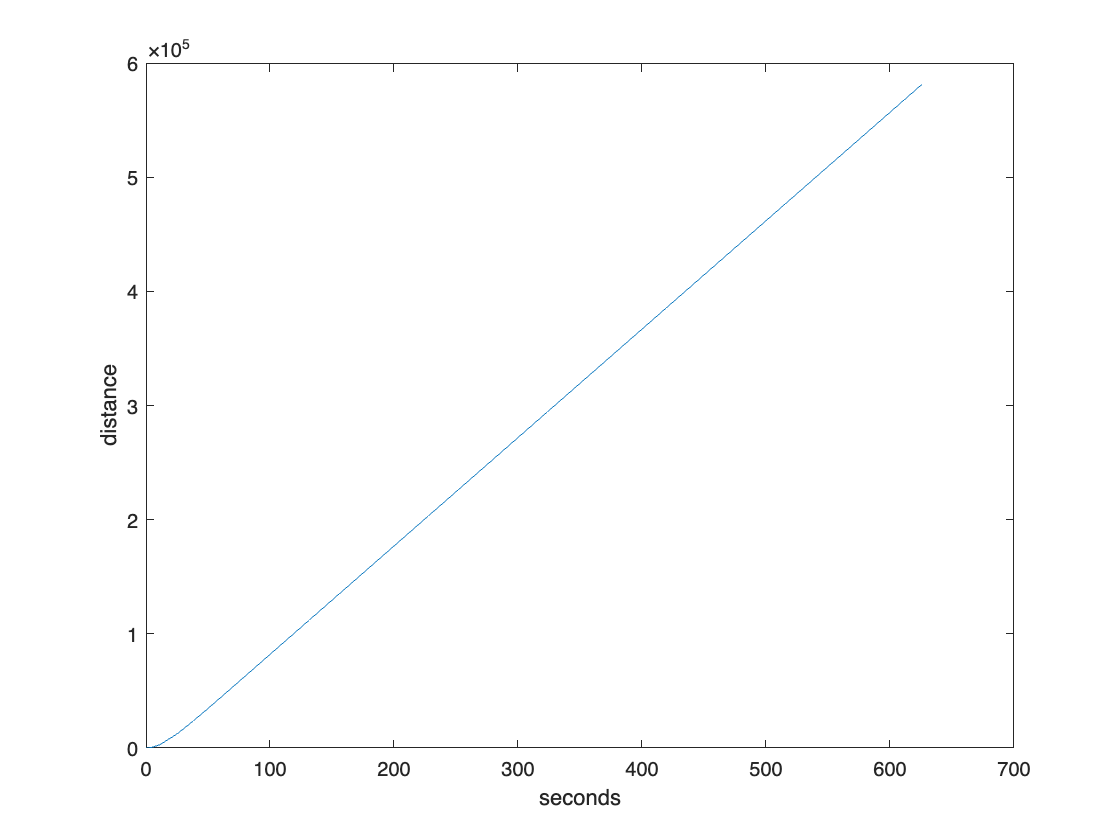

plot(l_out.yout{1}.Values.Time,l_out.yout{1}.Values.Data);
xlabel('seconds');
ylabel('distance');

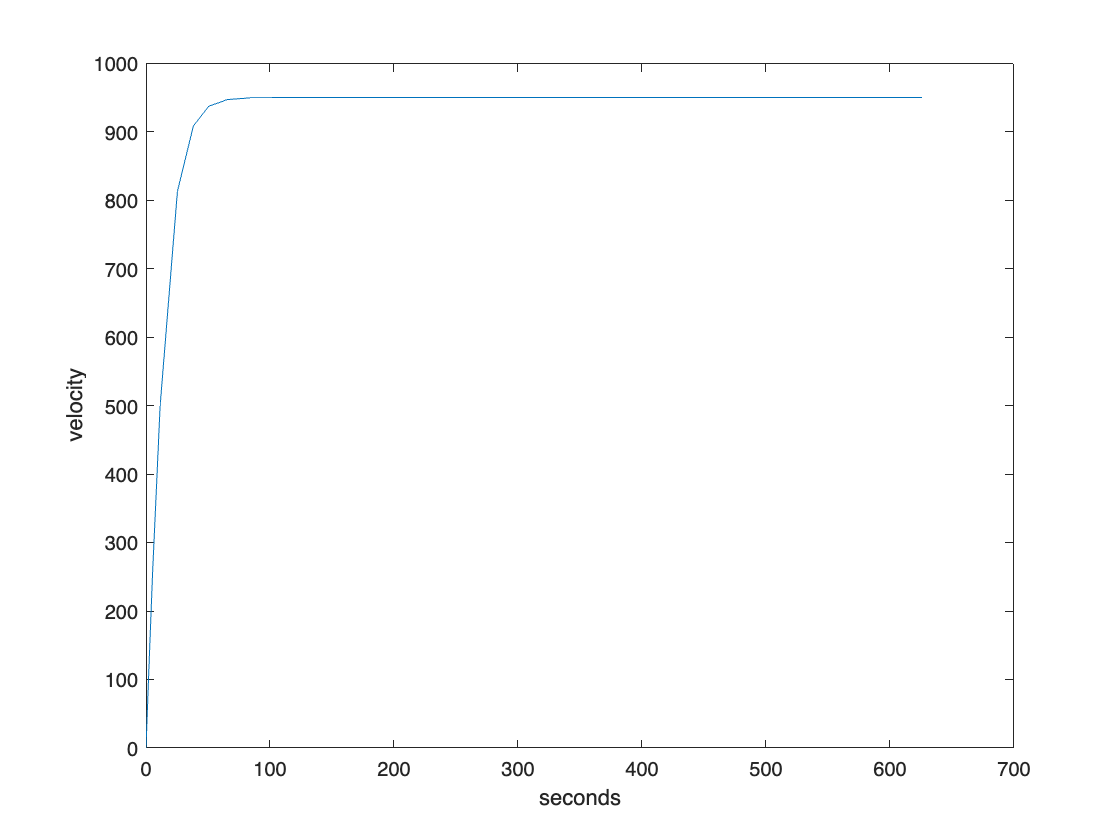

plot(l_out.yout{3}.Values.Time,l_out.yout{3}.Values.Data);
xlabel('seconds');
ylabel('velocity');

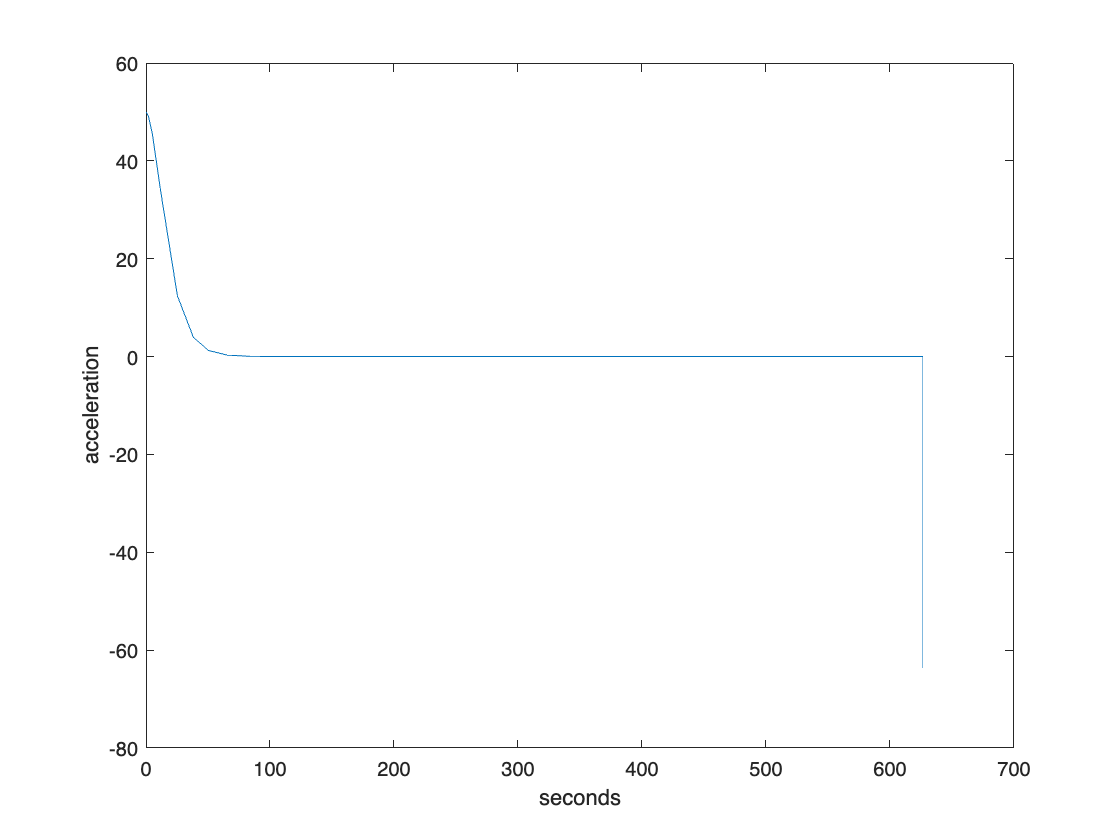

plot(l_out.yout{2}.Values.Time,l_out.yout{2}.Values.Data);
xlabel('seconds');
ylabel('acceleration');

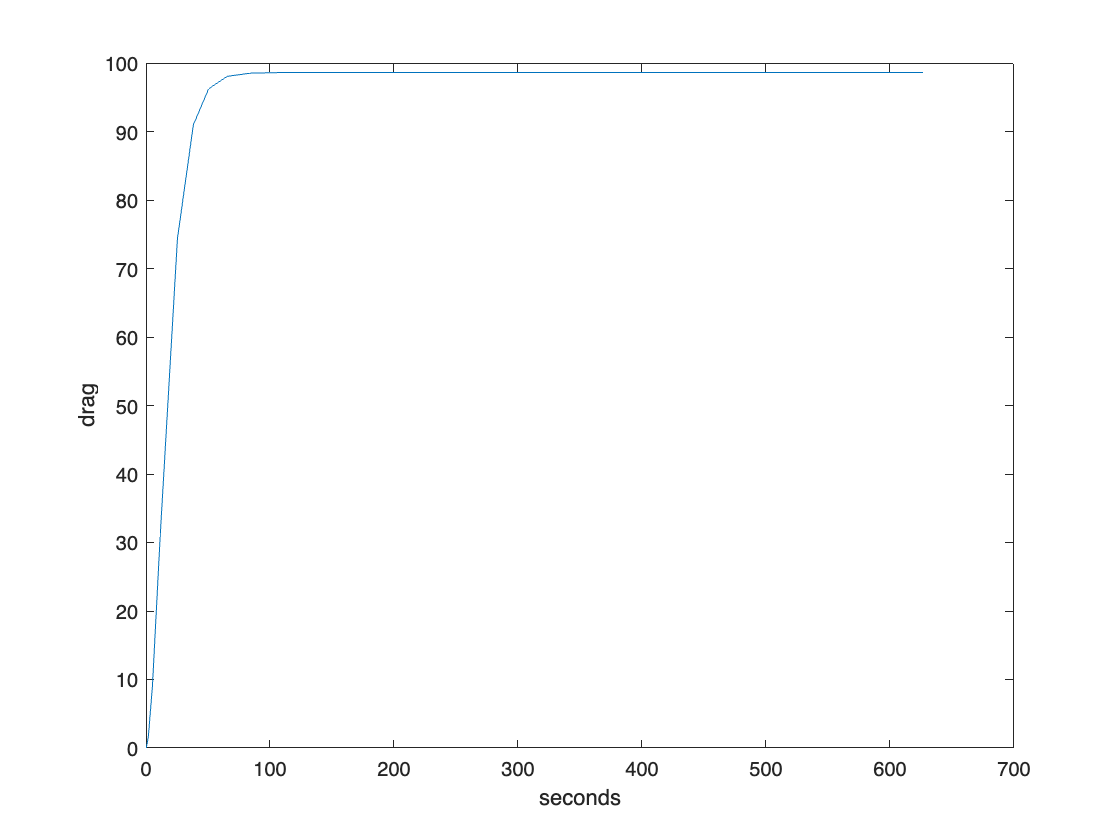

plot(l_out.yout{4}.Values.Time,l_out.yout{4}.Values.Data);
xlabel('seconds');
ylabel('drag');

fuel_time=max(l_out.tout) %s

fuel_time = 626.5543

fuel_time_minutes=fuel_time/60.0 %min

fuel_time_minutes = 10.4426

range=max(l_out.yout{1}.Values.Data) %ft

range = 5.8204e+05

range_miles=convlength(range,'ft','mi') % miles

range_miles = 110.2341

max_velocity_level=max(l_out.yout{3}.Values.Data) %ft/s

max_velocity_level = 949.6828

max_mach_level=max(l_out.yout{7}.Values.Data) %mach

max_mach_level = 0.8509

max_acceleration_level=max(l_out.yout{2}.Values.Data) %ft/s^2

max_acceleration_level = 49.9621

max_g_level=max(l_out.yout{2}.Values.Data)/G %g's

max_g_level = 1.5529

max_drag_level=max(l_out.yout{4}.Values.Data)%lbf

max_drag_level = 98.6250

### Vertical launch

Note: ran simlink model and rename out to r_out in workspace.

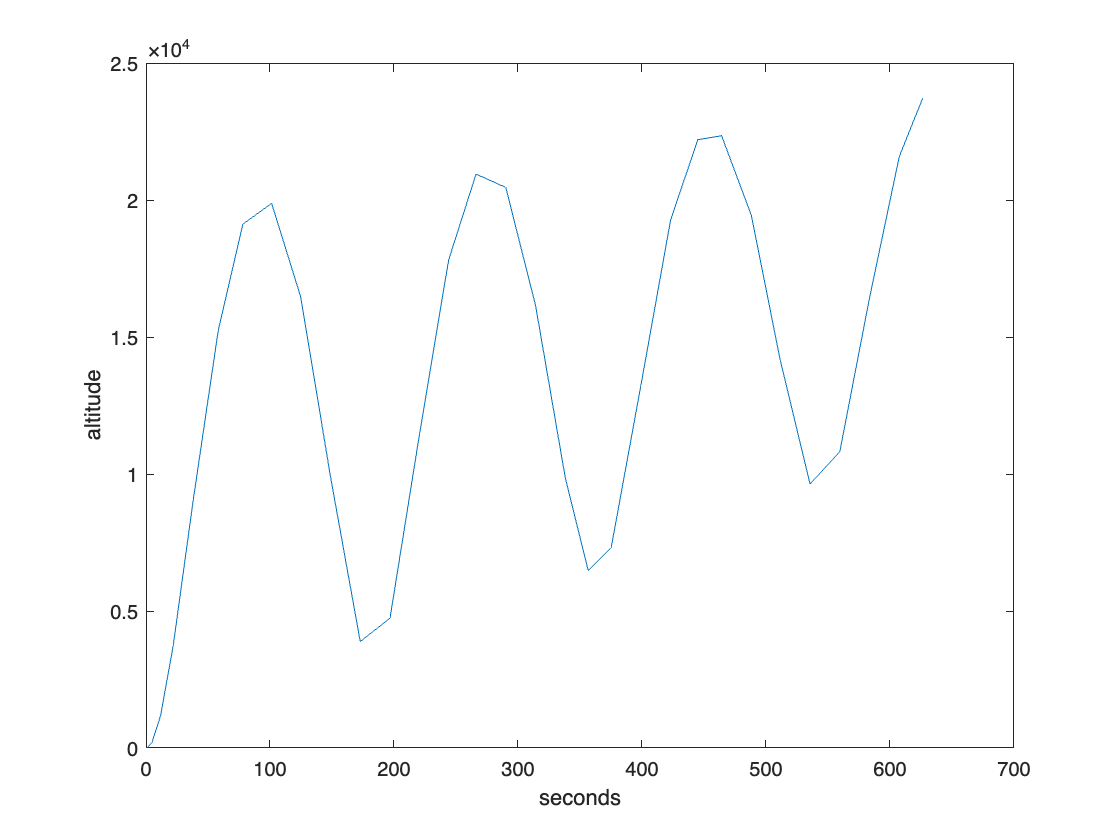

plot(r_out.yout{1}.Values.Time,r_out.yout{1}.Values.Data);
xlabel('seconds');
ylabel('altitude');

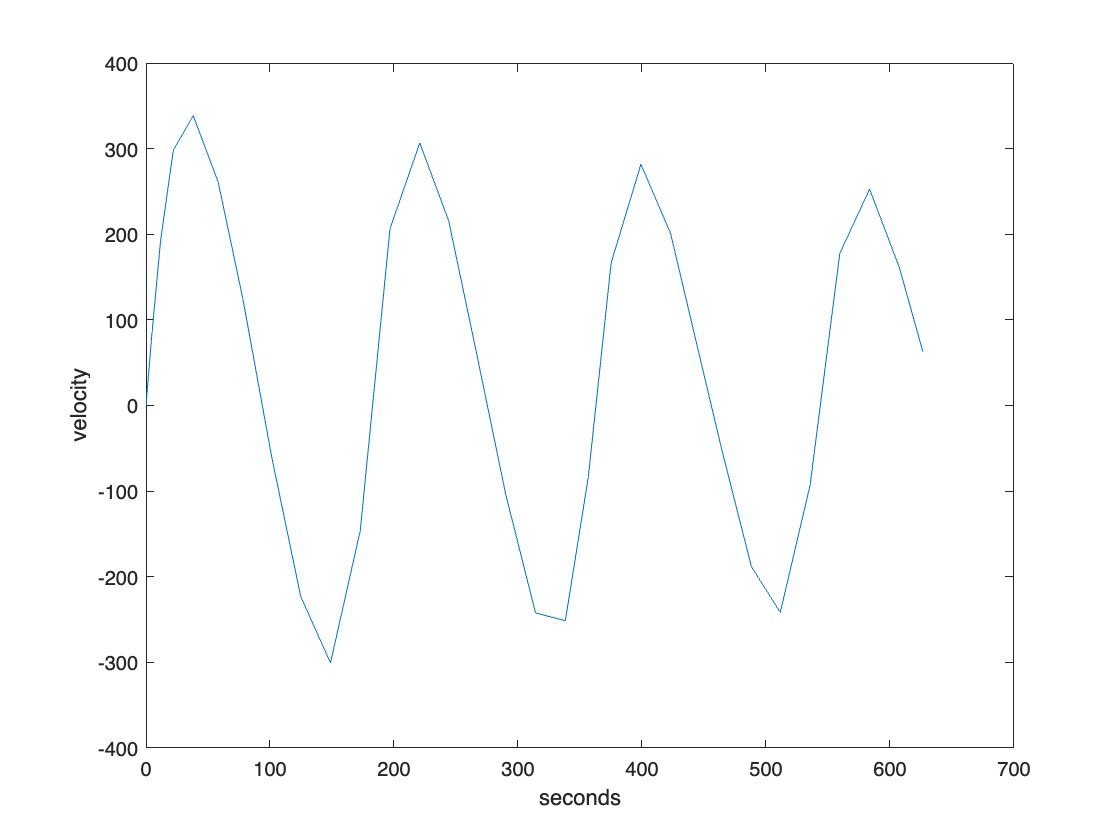

plot(r_out.yout{3}.Values.Time,r_out.yout{3}.Values.Data);
xlabel('seconds');
ylabel('velocity');

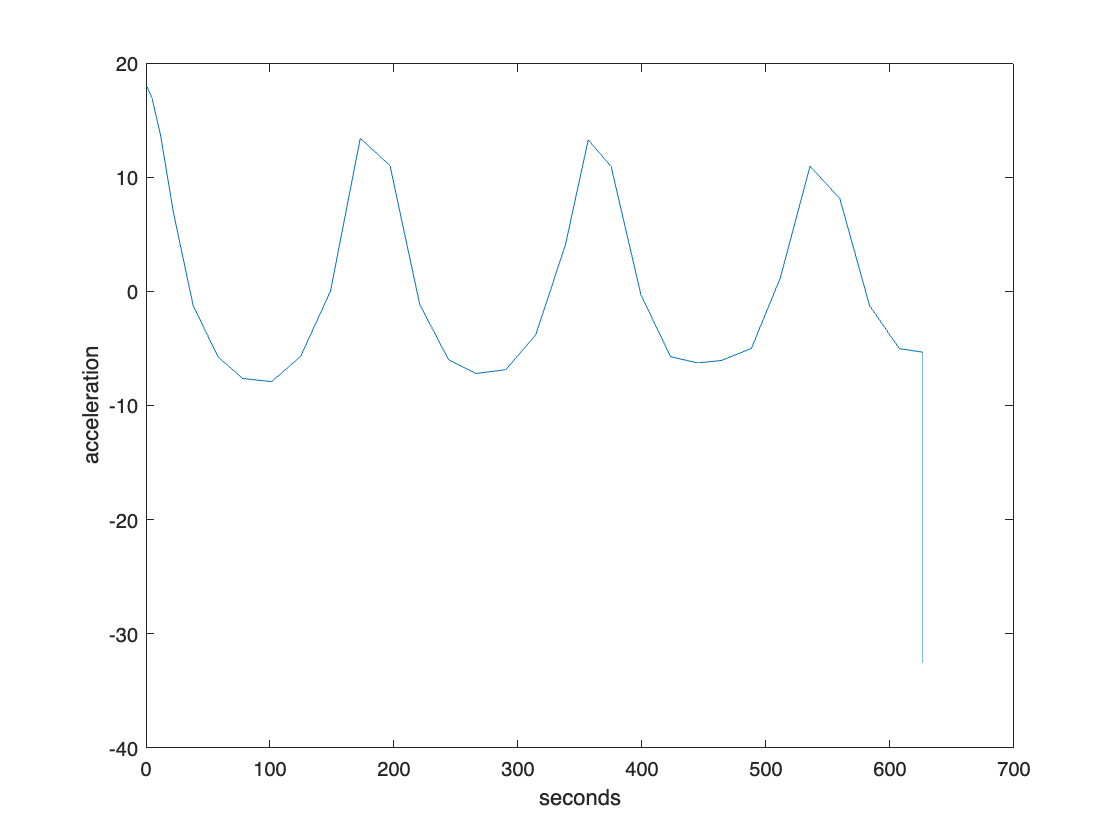

plot(r_out.yout{2}.Values.Time,r_out.yout{2}.Values.Data);
xlabel('seconds');
ylabel('acceleration');

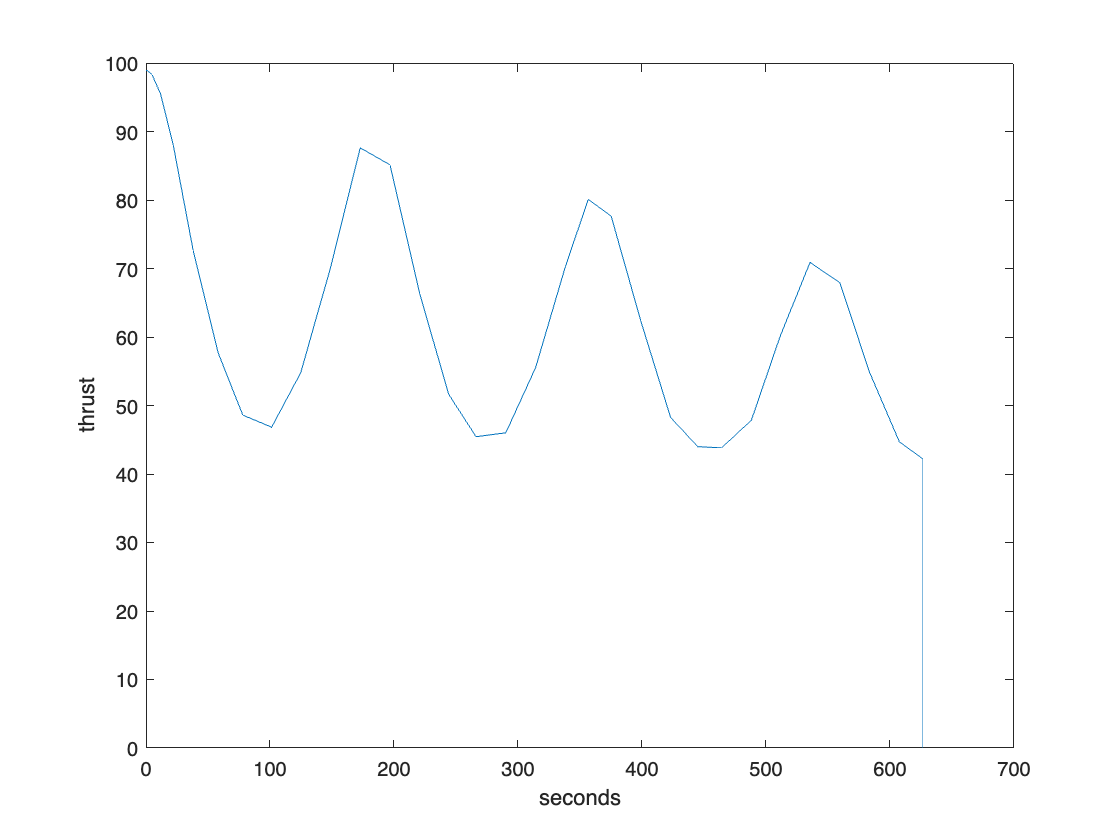

plot(r_out.yout{5}.Values.Time,r_out.yout{5}.Values.Data);
xlabel('seconds');
ylabel('thrust');

clip_index=20;% time ~ 133 s
max_altitude=max(r_out.yout{1}.Values.Data(1:clip_index)) %ft

max_altitude = 1.9876e+04

max_altitude_miles=convlength(max_altitude,'ft','mi') %mi

max_altitude_miles = 3.7643

max_velocity_launch=max(r_out.yout{3}.Values.Data(1:clip_index)) %ft/s

max_velocity_launch = 338.5472

max_velocity_launch_mach=max(r_out.yout{7}.Values.Data(1:clip_index)) %ft/s

max_velocity_launch_mach = 0.3131

max_acceleration_launch=max(r_out.yout{2}.Values.Data(1:clip_index)) %ft/s^2

max_acceleration_launch = 17.9360

max_g_launch=max(r_out.yout{2}.Values.Data(1:clip_index))/G %g's

max_g_launch = 0.5575

min_thrust_level=min(r_out.yout{5}.Values.Data(1:clip_index)) %lbf

min_thrust_level = 46.8379

### Save Workspace

Save the simulation data from workspace.

%save('RR_1DOF','l_out','r_out')